依赖[统一实验分析作图v17.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

DataSet=TransferLearning.FullCalcium;

统一实验分析作图v17.2.0已发布，<a href="https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases">立即更新</a>


光声迁移

LACalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'光声迁移'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1])

Colors =     1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000    0.0000


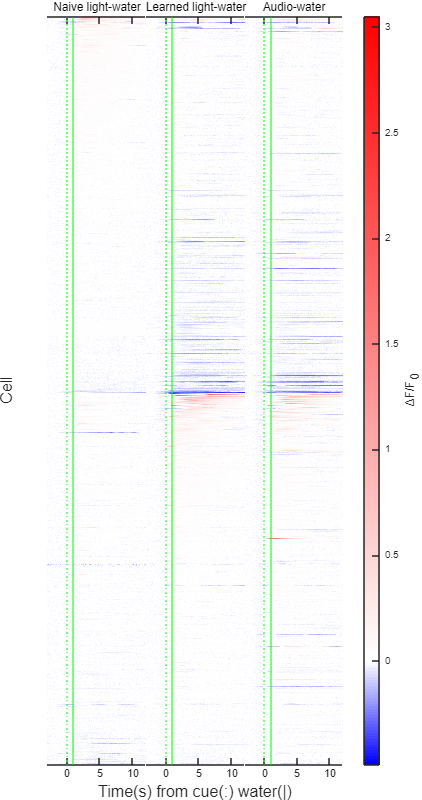

Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(LACalcium,["Naive_task_A","Learned_task_A"]).NTATS{:,:,["Naive_task_A","Learned_task_A","Task_B"]},["Naive light-water","Learned light-water","Audio-water"],Colors([2,1,3],:),false);
MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('Fig1G.svg'),'-dsvg');

声光迁移

ALCalcium=DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'声光迁移'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median);

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1])

Colors =     1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000    0.0000


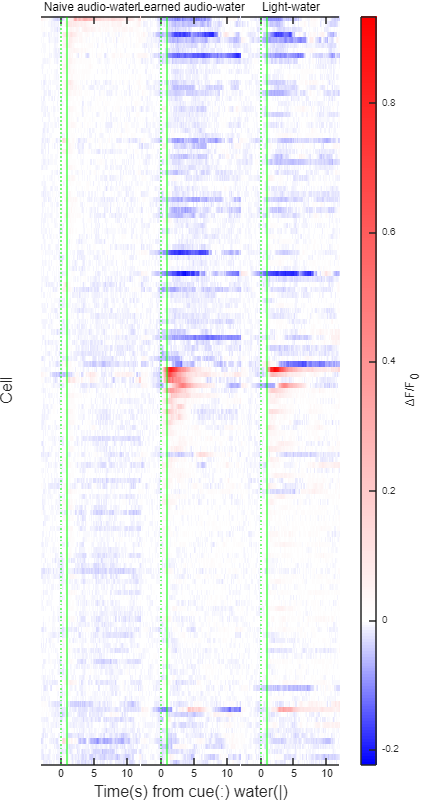

Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(ALCalcium,["Naive_task_A","Learned_task_A"]).NTATS{:,:,["Naive_task_A","Learned_task_A","Task_B"]},["Naive audio-water","Learned audio-water","Light-water"],Colors([2,1,3],:),false);
MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('FigS1G.svg'),'-dsvg');

声光迁移RSPd

QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'声光迁移RSPd');
RSPdCalcium=DataSet.QueryNTATS(QueryTable,UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median);

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1])

Colors =     1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000    0.0000


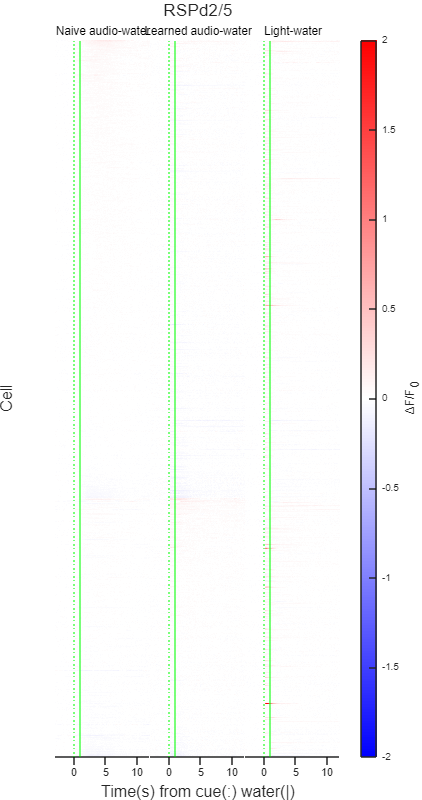

Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(RSPdCalcium,["Naive_task_A","Learned_task_A"]).NTATS{:,:,["Naive_task_A","Learned_task_A","Task_B"]},["Naive audio-water","Learned audio-water","Light-water"],Colors([2,1,3],:),false,[-2,2]);
title(Layout,'RSPd2/5');
MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('FigS1F.svg'),'-dsvg');

QueryTable.GroupName(:)="All";

NumMice=numel(unique(DataSet.TableQuery("Mouse",QueryTable).All.Mouse))

NumMice = 4